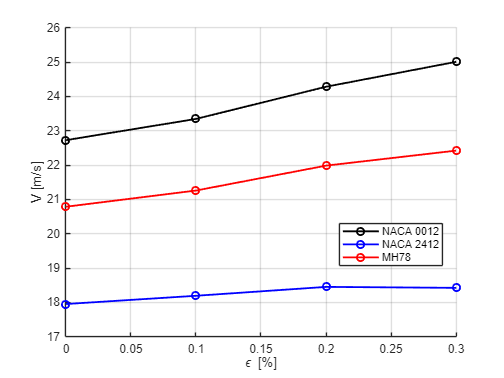

close all
clear
clc

load('multiple_sims_results.mat');

airfoils_vec = {"n0012", "naca2412", "mh78"};
root_vec = [0, 0.1, 0.2, 0.3];
twist_vec = [0, 5, 10, 15];
lambda_vec = [0.3 0.5 0.75, 1];

colors = {"k-o", "b-o", "r-o"};

% Pasta para salvar imagens
output_dir = 'figs/';
if ~exist(output_dir, 'dir')
    mkdir(output_dir)
end

% --------------------------
% Variação com root
% --------------------------

figure()
hold on; grid on;
set(gcf, 'Color', 'w')  % fundo branco para EPS
for ii = 1:length(airfoils_vec)
    plot(root_vec, squeeze(-v(ii, :, 1, 1)), colors{ii}, 'LineWidth', 1.5)
end
legend("NACA 0012", "NACA 2412", "MH78", "Location", "best")
xlabel("\epsilon [%]")
ylabel("V [m/s]")
exportgraphics(gcf, fullfile(output_dir, 'V_vs_root.eps'), 'ContentType', 'vector')

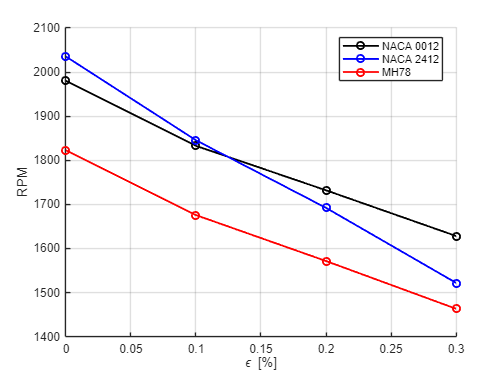


figure()
hold on; grid on;
set(gcf, 'Color', 'w')
for ii = 1:length(airfoils_vec)
    plot(root_vec, squeeze(rpm(ii, :, 1, 1)) * 60 / (2*pi), colors{ii}, 'LineWidth', 1.5)
end
legend("NACA 0012", "NACA 2412", "MH78", "Location", "best")
xlabel("\epsilon [%]")
ylabel("RPM")
exportgraphics(gcf, fullfile(output_dir, 'RPM_vs_root.eps'), 'ContentType', 'vector')

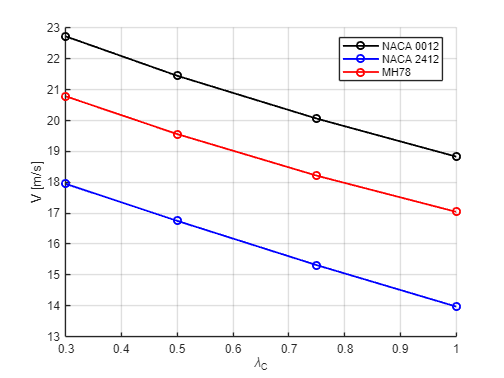


% --------------------------
% Variação com lambda
% --------------------------

figure()
hold on; grid on;
set(gcf, 'Color', 'w')
for ii = 1:length(airfoils_vec)
    plot(lambda_vec, squeeze(-v(ii, 1, 1, :)), colors{ii}, 'LineWidth', 1.5)
end
legend("NACA 0012", "NACA 2412", "MH78", "Location", "best")
xlabel("\lambda_C")
ylabel("V [m/s]")
exportgraphics(gcf, fullfile(output_dir, 'V_vs_lambda.eps'), 'ContentType', 'vector')

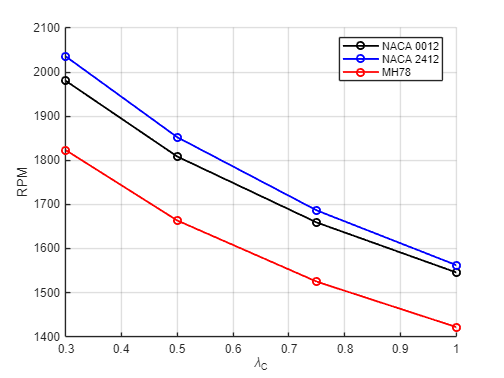


figure()
hold on; grid on;
set(gcf, 'Color', 'w')
for ii = 1:length(airfoils_vec)
    plot(lambda_vec, squeeze(rpm(ii, 1, 1, :)) * 60 / (2*pi), colors{ii}, 'LineWidth', 1.5)
end
legend("NACA 0012", "NACA 2412", "MH78", "Location", "best")
xlabel("\lambda_C")
ylabel("RPM")
exportgraphics(gcf, fullfile(output_dir, 'RPM_vs_lambda.eps'), 'ContentType', 'vector')

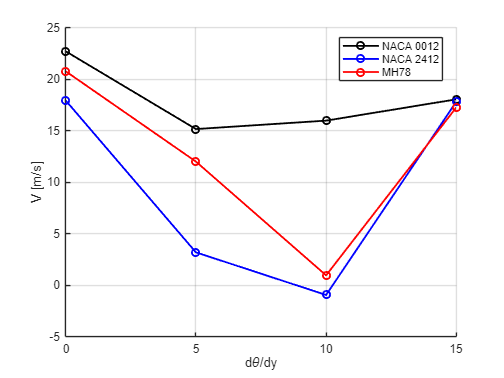


% --------------------------
% Variação com twist
% --------------------------

figure()
hold on; grid on;
set(gcf, 'Color', 'w')
for ii = 1:length(airfoils_vec)
    plot(twist_vec, squeeze(-v(ii, 1, :, 1)), colors{ii}, 'LineWidth', 1.5)
end
legend("NACA 0012", "NACA 2412", "MH78", "Location", "best")
xlabel("d\theta/dy")
ylabel("V [m/s]")
exportgraphics(gcf, fullfile(output_dir, 'V_vs_twist.eps'), 'ContentType', 'vector')

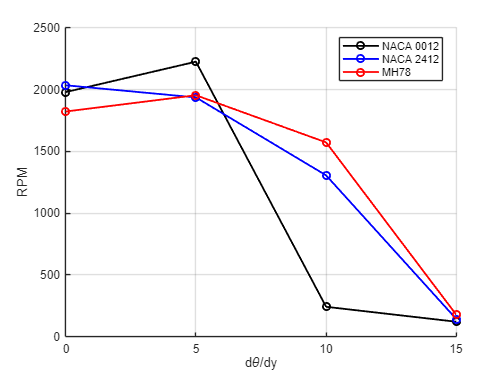


figure()
hold on; grid on;
set(gcf, 'Color', 'w')
for ii = 1:length(airfoils_vec)
    plot(twist_vec, squeeze(rpm(ii, 1, :, 1)) * 60 / (2*pi), colors{ii}, 'LineWidth', 1.5)
end
legend("NACA 0012", "NACA 2412", "MH78", "Location", "best")
xlabel("d\theta/dy")
ylabel("RPM")
exportgraphics(gcf, fullfile(output_dir, 'RPM_vs_twist.eps'), 'ContentType', 'vector')